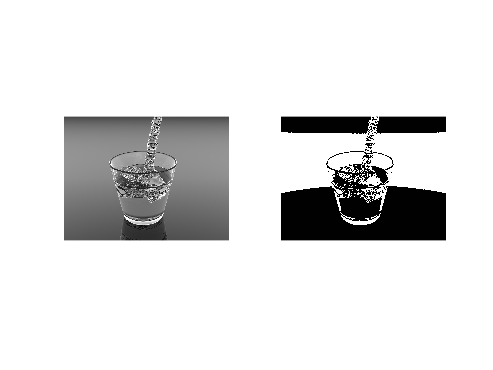

% Exercise1: Changing the number of gray Levels
% ex1.m
% Changing the Gray Resolution

clc;
clear all;
I = imread('C:\Users\SIACLAB03PC04\Desktop\DIP\P1\img1.jpg');
K= imfinfo('C:\Users\SIACLAB03PC04\Desktop\DIP\P1\img1.jpg');
if(K.BitDepth ==24)
 % so the image is RGB
 I=rgb2gray(I);
end
[r,c] = size(I); % 256*256
I2= uint8(zeros(r,c)); %256*256 matrix of zeros
for i = 1:r
 for j=1:c
 if (I(i,j)>128)
 I2(i,j) =255;
 else
 I2(i,j) =1;
 end
 end
end
figure
subplot(121),imshow(I);
subplot(122),imshow(I2);